% Get all .wav files in the directory
files = dir(fullfile('Training_Data', '*.wav'));

% Extract numeric values from filenames for correct sorting
fileNames = {files.name};
numValues = zeros(length(fileNames), 1);

for i = 1:length(fileNames)
    numStr = regexp(fileNames{i}, '\d+', 'match'); % Extract numeric part
    numValues(i) = str2double(numStr{1}); % Convert to number
end

% Sort files numerically
[~, sortedIdx] = sort(numValues);
files = files(sortedIdx); % Reorder file structure

% Number of files
numFiles = length(files);
mfcc_data = cell(1, numFiles); %creates a cell array

for i = 1:numFiles
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end

    %use cell array to save data
    mfcc_data{i} = our_mfcc(signal,fs);
 
    %loaded_data = load('mfcc_data.mat');
    %mfcc_data_loaded = loaded_data.mfcc_data;
 

    %builtin_mfcc = mfcc(signal,fs,"NumCoeffs",19);
    %disp(builtin_mfcc);


end


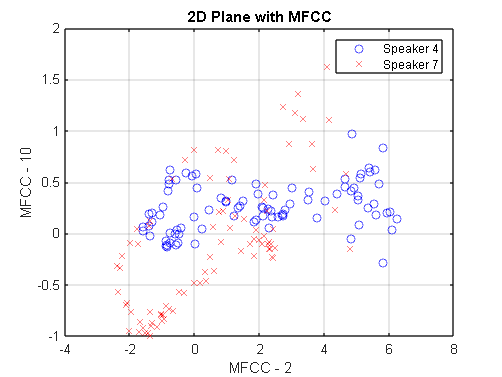

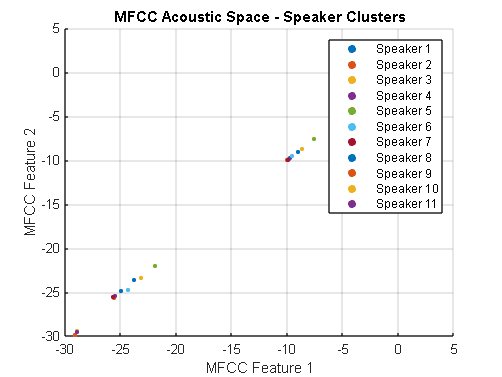

%% TEST 5
figure;
plot(mfcc_data{4}(2,:)',mfcc_data{4}(10,:)','o','Color','b');
hold on
grid on

plot(mfcc_data{7}(2,:),mfcc_data{7}(10,:)','x','Color','r');
legend('Speaker 4','Speaker 7');
title('2D Plane with MFCC');
xlabel('MFCC - 2');
ylabel('MFCC - 10');